# Bridge of Doom Project

### Code for traversing bridge

clear;
syms u;
% beta * t = u
% lower beta = lower speed
beta = 0.1;
timeBounds = [0 (3.2/beta)];

% Define equations
r = 4*[0.396*cos(2.65*(beta*u+1.4));...
   -0.99*sin(beta*u+1.4);...
   0];

% Assume u is positive
assume(u,{'real','positive'})

% ---- FIND UNIT TANGENT VECTOR ----
dr=diff(r,u);
T_hat=simplify(dr./norm(dr))

% ---- FIND UNIT NORMAL VECTOR----
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

% ---- FIND VELOCITY ----
speed = simplify(norm(dr))

% ---- FIND ANGULAR VELOCITY ----
angular_velocity = simplify(cross(T_hat,dT_hat))

% ---- FIND WHEELS ----
d = 0.235;
v_left_wheel = simplify(speed - d/2*angular_velocity(3));
v_right_wheel = simplify(speed + d/2*angular_velocity(3));

% stop the robot if it's going right now
pub = rospublisher('raw_vel', 'islatching', false);
stop;

bridgeStart = double(subs(r,u,0));
startingThat = double(subs(T_hat,u,0));
placeNeato(bridgeStart(1),  bridgeStart(2), startingThat(1), startingThat(2));

% wait a bit for robot to fall onto the bridge
pause(2);

% start tracking time
rostic;
% time to drive!!
while true
    % get current time
    % timeBounds(1) is the beginning time
    u_val = rostoc() + timeBounds(1);

    % timeBounds 2 is the end time
    if u_val > timeBounds (2)
        break
    end
    msg = rosmessage(pub);
    leftSpeed = double(subs(v_left_wheel, u, u_val))
    rightSpeed = double(subs(v_right_wheel, u, u_val))

    msg.Data = [leftSpeed, rightSpeed];
    % send to the robot
    send(pub, msg);
    % wait a little bit before the next iteration
    pause(0.01);
end
stop;

$$T\_hat = \begin{array}{l} \left(\begin{array}{c} -\frac{53\,\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}{\sigma_{1}}\\ -\frac{50\,\cos\left(\frac{u}{10}+\frac{7}{5}\right)}{\sigma_{1}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}^{2}} \end{array}$$

$$N\_hat = \begin{array}{l} \left(\begin{array}{c} -\frac{2\,\left(96725\,\sigma_{6}+140450\,\sigma_{5}+43725\,\sigma_{4}\right)}{\sigma_{1}}\\ \frac{112360\,\sin\left(\frac{u}{10}+\frac{7}{5}\right)+205057\,\sigma_{3}+92697\,\sigma_{2}}{\sigma_{1}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=53\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{u}{10}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{100}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{100}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{200}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{200}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{200}+\frac{91}{100}\right) \end{array}$$

$$speed = \frac{99\,\sqrt{2500\,{\cos\left(\frac{u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}$$

$$angular\_velocity = \left(\begin{array}{c} 0\\ 0\\ -\frac{3869\,\cos\left(\frac{33\,u}{200}+\frac{231}{100}\right)+1749\,\cos\left(\frac{73\,u}{200}+\frac{511}{100}\right)}{10000\,\cos\left(\frac{u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{53\,u}{100}+\frac{371}{50}\right)+21236} \end{array}\right)$$

## Plotting

### Define linspace for u for plotting

% define 100evenly spaced points between 0 and 3.2
u_num = linspace(0,3.2/beta,100); 

### Load csv

data = readtable("bod_data.csv", "Delimiter", ",");
data_size = size(data, 1);
data.time = data.time - data.time(1);

data_time = (data.time ./ data.time(data_size)) * (3.2/beta);

### Calculate actual velocities for left and right wheel, speed, angular velocity

r_actual_i =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


r_actual_j =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


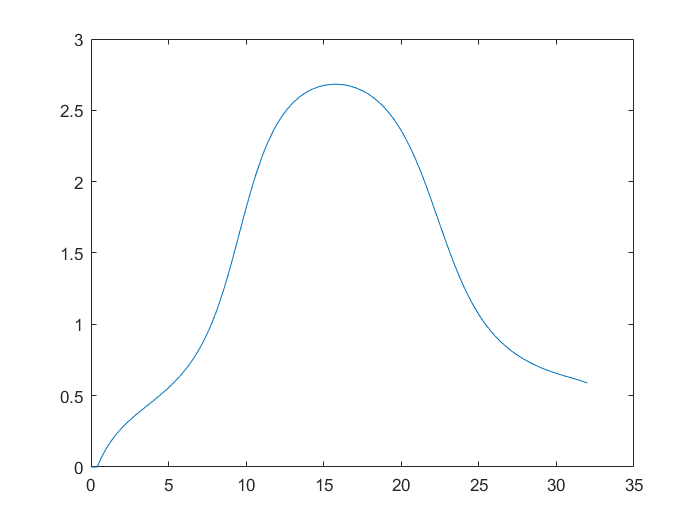

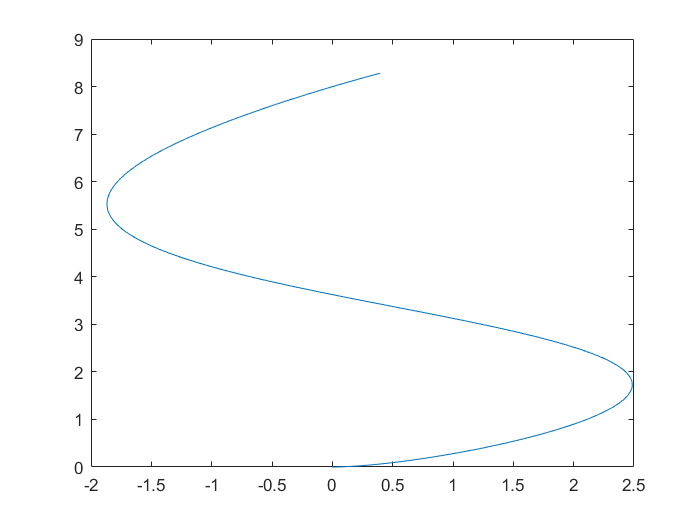

v_left_actual = zeros(1, data_size);
v_right_actual = zeros(1, data_size);
speed_actual = zeros(1, data_size);
angular_velocity_actual = zeros(1, data_size);

for i=1:(data_size - 1)
    v_left_actual(i) = (data.encoderLeft(i+1) - data.encoderLeft(i))/(data.time(i+1) - data.time(i));
    v_right_actual(i) = (data.encoderRight(i+1) - data.encoderRight(i))/(data.time(i+1) - data.time(i));
    speed_actual(i) = (v_left_actual(i) + v_right_actual(i))/2;
    angular_velocity_actual(i) = (v_right_actual(i) - v_left_actual(i))/d;
end

### Plot Speed

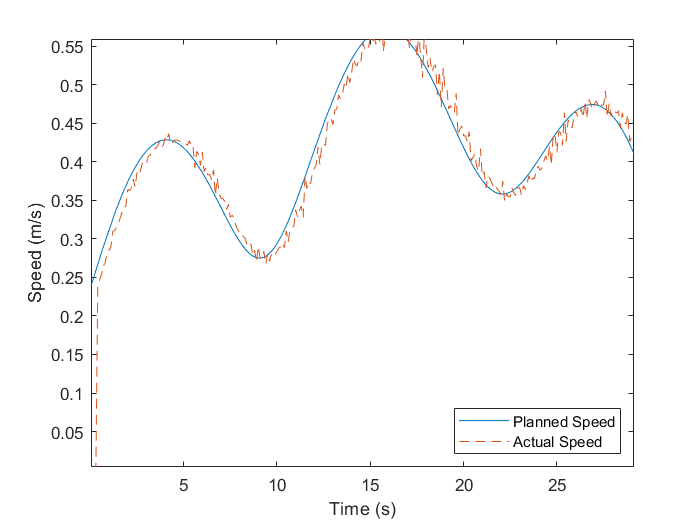

clf;
fplot(speed,[0 3.2/beta]); hold on;
plot(data.time, speed_actual, '--');
xlabel('Time (s)')
ylabel('Speed (m/s)')
legend('Planned Speed', 'Actual Speed','Location','southeast')

### Plot Angular Velocity

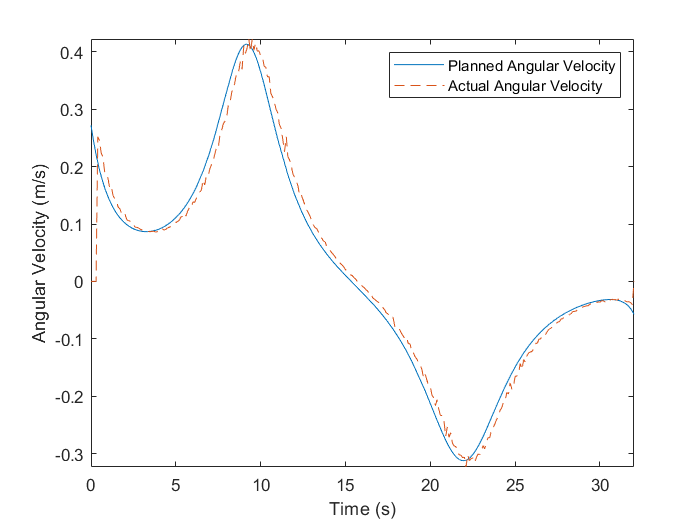

clf;
fplot(angular_velocity(3),[0 3.2/beta]); hold on;
plot(data.time, angular_velocity_actual, '--')
xlabel('Time (s)')
ylabel('Angular Velocity (m/s)')
legend('Planned Angular Velocity', 'Actual Angular Velocity','Location','northeast')

### Plot Left and Right Wheel Velocities

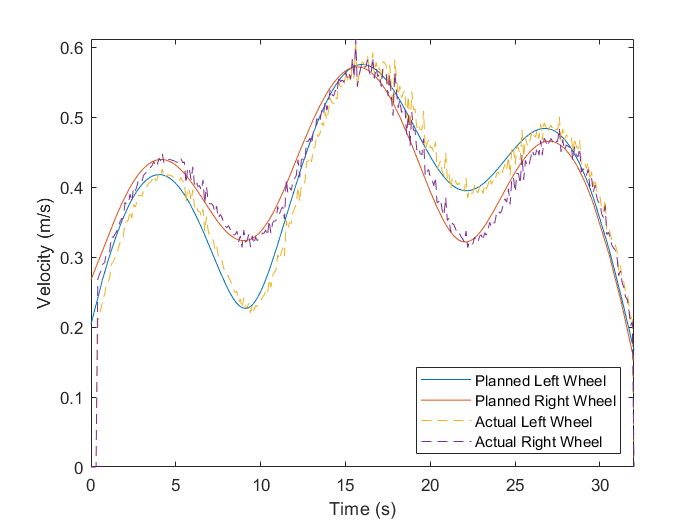

clf; 
fplot(norm(v_left_wheel),[0 3.2/beta]); hold on;
fplot(norm(v_right_wheel),[0 3.2/beta]);
plot(data.time, v_left_actual, '--');
plot(data.time, v_right_actual, '--'); hold off;


xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('Planned Left Wheel', 'Planned Right Wheel', 'Actual Left Wheel', 'Actual Right Wheel', 'Location', 'southeast')

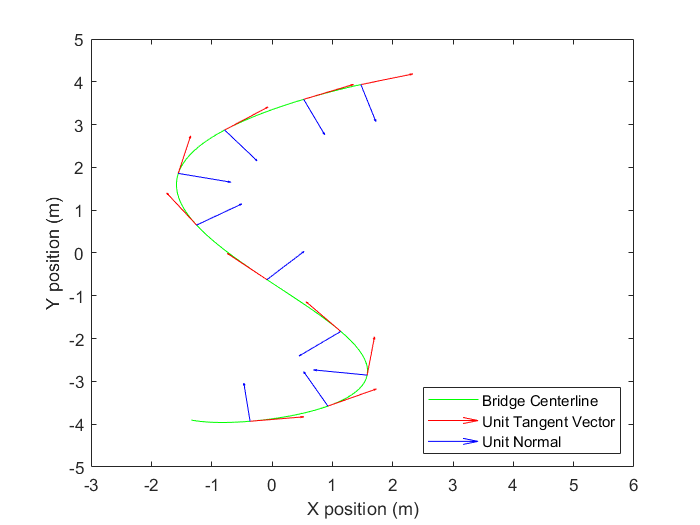

clf;

for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[u],[u_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[u],[u_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[u],[u_num(n)]));
    
    if n == 1
        plot(r_num(:,1),r_num(:,2),'g'),axis([-3 6 -5 5]),hold on % plot the entire curve
    end
    
    % plot the vectors less frequently
    if mod(n, 10) == 0 || n == length(u_num)
        quiver(r_num(n,1),r_num(n,2),T_hat_num(n,1),T_hat_num(n,2),'r') % plot the unit tangent
        quiver(r_num(n,1),r_num(n,2),N_hat_num(n,1),N_hat_num(n,2),'b') % plot the unit normal
    end
end
drawnow % force the graphic to update as it goes
xlabel('X position (m)')
ylabel('Y position (m)')
legend('Bridge Centerline', 'Unit Tangent Vector', 'Unit Normal','Location','southeast'); hold off;

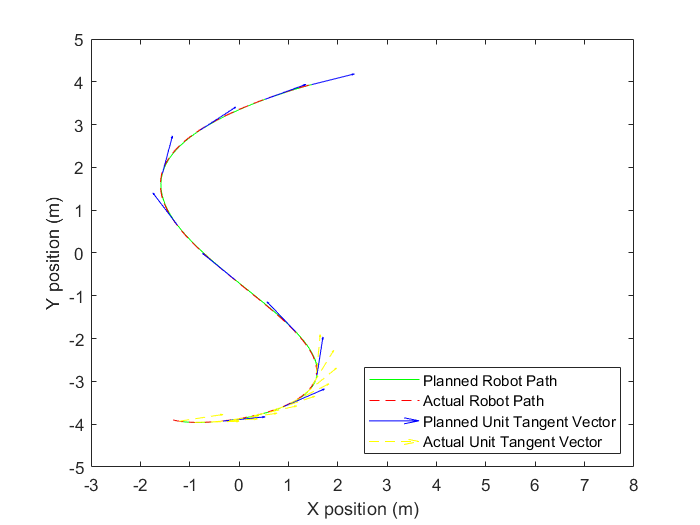

clf;
plot(r_num(:,1),r_num(:,2),'g'),axis([-3 8 -5 5]),hold on % plot the entire curve
theta = zeros(1, data_size);
r_actual = zeros(data_size, 2);
T_hat_actual = zeros(data_size, 2);

% initial values
% start with the same values as the parametric curve equation
theta(1) = atan(T_hat_num(1,2) / T_hat_num(1,1)); % calculate initial theta from initial T hat
r_actual(1,1) = r_num(1,1);
r_actual(1,2) = r_num(1,2); 
for i=2:data_size
    delta_time = data.time(i) - data.time(i-1);
    theta(i) = theta(i-1) + angular_velocity_actual(i-1) * delta_time;
    r_actual(i, 1) = r_actual(i-1,1) + speed_actual(i-1) * cos(theta(i)) * delta_time;
    r_actual(i, 2) = r_actual(i-1,2) + speed_actual(i-1) * sin(theta(i)) * delta_time;
    
    % get unit tangent
    T_hat_actual(i,1) = sqrt(1 / (1 + (tan(theta(i)))^2));
    T_hat_actual(i,2) = sqrt(1 - T_hat_actual(i,1)^2);
end
plot(r_actual(:,1), r_actual(:,2), 'r--')

% now plot unit tangent
for n=1:length(u_num)
    if mod(n, 10) == 0 || n == length(u_num)
        quiver(r_num(n,1),r_num(n,2),T_hat_num(n,1),T_hat_num(n,2), 'b') % plot predicted unit tangent
        quiver(r_actual(n,1),r_actual(n,2),T_hat_actual(n,1),T_hat_actual(n,2), 'y--') % plot actual unit tangent
    end
end

xlabel('X position (m)')
ylabel('Y position (m)')
legend('Planned Robot Path', 'Actual Robot Path', 'Planned Unit Tangent Vector', 'Actual Unit Tangent Vector', 'Location','southeast'); hold off;